# Estimation, Filtering and Detection

## Homework 3B: Current Sensor Fault

## Timur Uzakov

## MACROS

clear all;
storeFigures = true; % set true if you want to save plots

## Problem 1:

% Design healthy (m=1) state-space model
% Design faulty  (m=2) state-space model
% Find controller gain K_p to keep current limited to 200 A and no
% overshoot
% Analyze observability of m1
% Analyze observability of m2

% Motor parameters
R = 0.1;                % Ohms
L = 0.5;                % Henrys
Km = 0.5;               % motor constant
J = 10;                 % kg.m^2/s^2
Kp = 2;
% Healthy system m=1

A = [0 Km/J; -Kp/L -(R+Km)/L];
B = [0 1/J; Kp/L 0];
C = [1 0;0 1];
D = 0;
sys_healthy = ss(A,B,C,D);

% Faulty system m=2

A_f = A;
B_f = B;
C_f = [1 0;0 0];
D_f = 0;
sys_faulty = ss(A_f,B_f,C_f,D_f);

% Observability
disp("Observability of healthy system")

Observability of healthy system


Ob_healthy = obsv(A,C);
unobsv = length(A) - rank(Ob_healthy)

unobsv = 0

disp("Observability of faulty system")

Observability of faulty system


Ob_faulty = obsv(A_f,C_f);
unobsv = length(A_f) - rank(Ob_faulty)

unobsv = 0

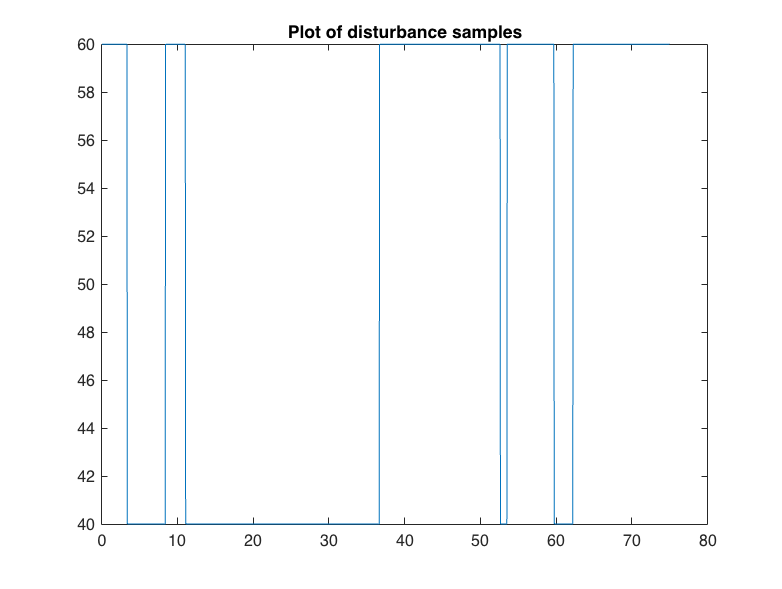




% disturbance
Ts = 0.05;
N = 1500;
T = Ts*(N-1);
t = 0:Ts:T;
load = 50;        % Nm
deviation = 10;
Td = load*ones(1,N); % load disturbance
p_switch = 0.005;
UU = ones(N,1);
for i=2:(N-1)
     if rand(1)<p_switch, UU(i)=-UU(i-1); else UU(i)=UU(i-1); end
end
Td = Td + deviation*UU';
figure(1);
plot(t,Td);
title("Plot of disturbance samples");

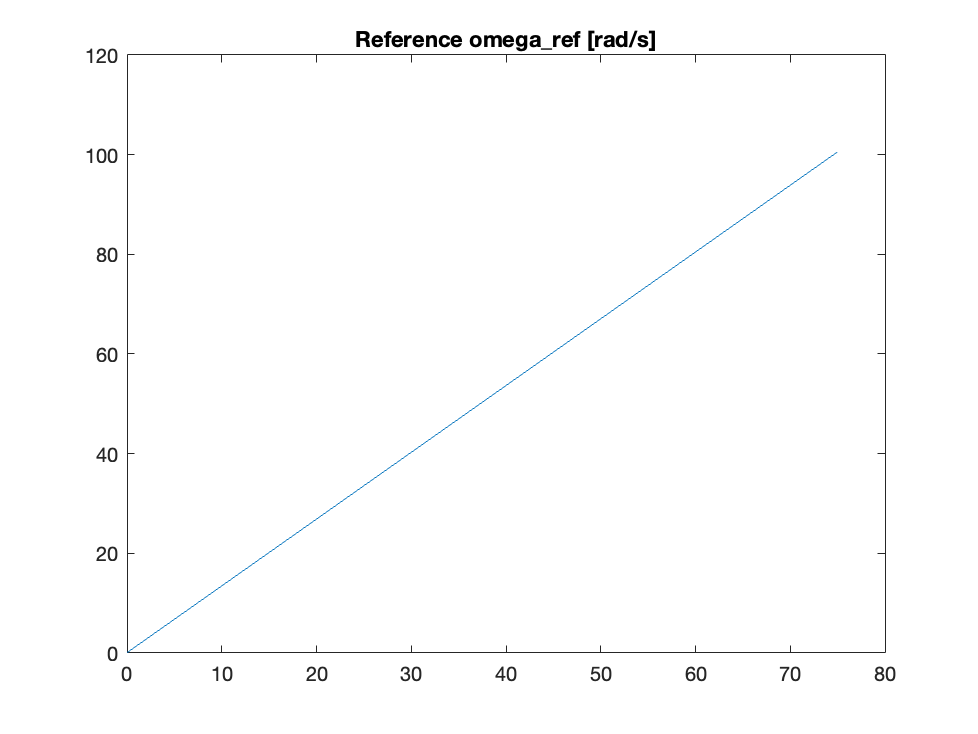


% refference signal
w_ref = zeros(1,N);
for i=1:length(t)
    w_ref(i) = w_ref(i) + 0.067*i;
end
figure(2);
plot(t,w_ref);
title("Reference omega\_ref [rad/s]");

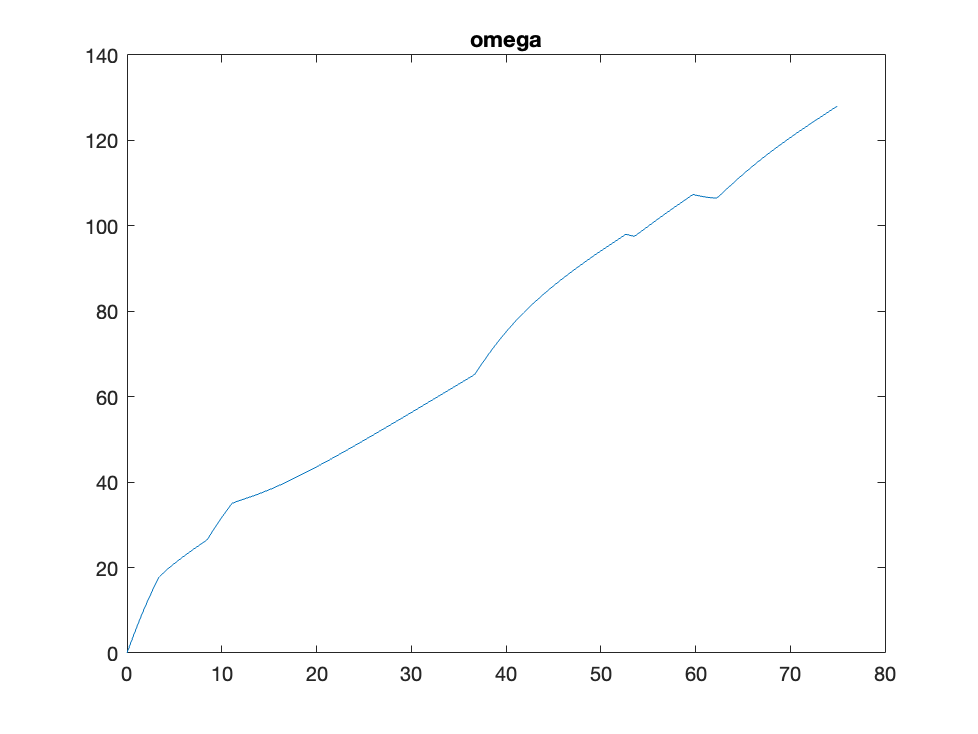


u = [w_ref;Td];
response = lsim(sys_healthy,u,t);
figure(3);
plot(t,response(:,1));
title("omega");

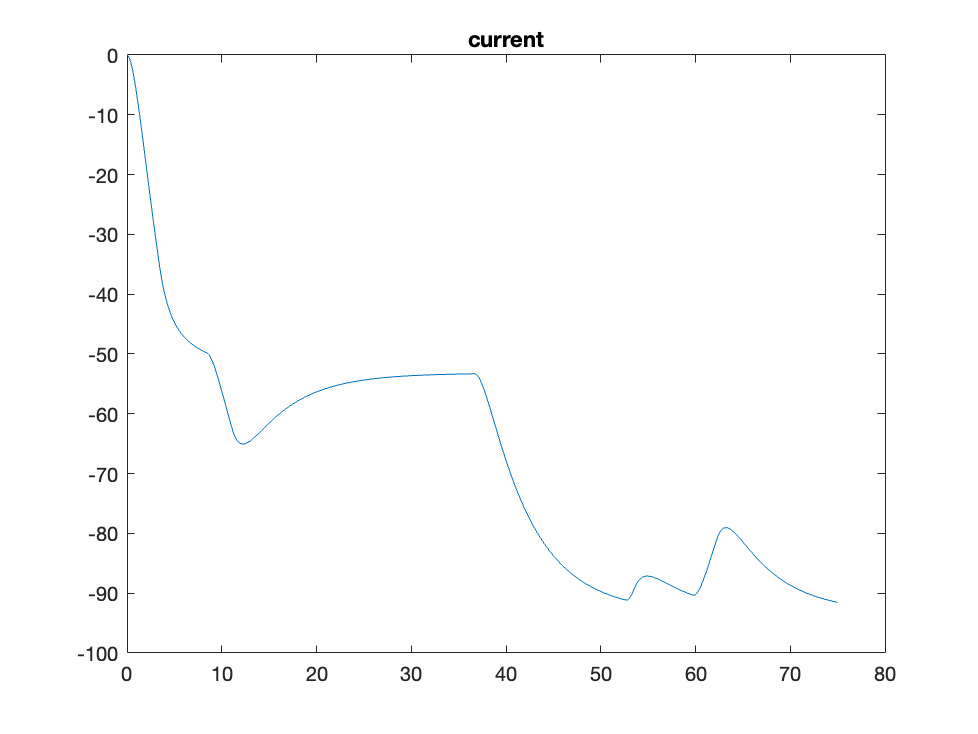

figure(4);
plot(t,response(:,2));
title("current");

## Problem 2:

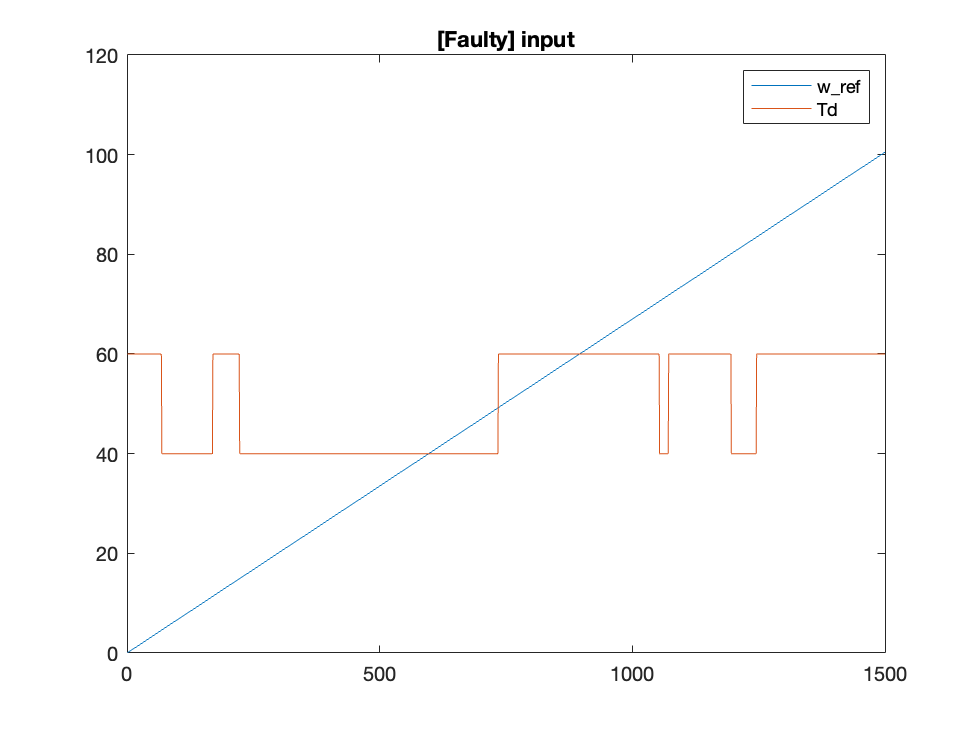

% Select and justify process noise properties
% Find input-output data with multiple sensor faults

% noise properties
Q = 0.4;
Q_f = 0.1;
R_cov = 0.1;
etta = 1; % selected as 1 (Tc=0) for synchronous sampling purposes

% healthy
Ah = expm(A*Ts);
Ch = C*expm(A*etta*Ts);

funB = @(x) expm(A.*x);
funD = @(x) expm(A.*x);
funQ = @(x) Q.*expm(A.*x)*expm(A'.*x);
funS = @(x) Q.*expm(A.*x)*expm(A'.*x)*C';
funR = @(x) Q.*C*expm(A.*x)*expm(A'.*x)*C';

Bh = integral(funB,0,Ts,'ArrayValued', true);
Dh = integral(funD,0,etta*Ts,'ArrayValued', true);
Qh = integral(funQ,0,Ts,'ArrayValued', true);
Sh = integral(funS,0,etta*Ts,'ArrayValued', true);
Rh = integral(funR,0,etta*Ts,'ArrayValued', true);
Bh = Bh*B;
Dh = C*Dh*B;
Rh = R_cov + Rh;
% Qh = Q*inv(A+A')*(expm((A+A')*Ts) -expm((A+A')*0));
% Sh = Q*inv(A+A')*(expm((A+A')*etta*Ts) -expm((A+A')*0))*C';
% Rh = R_cov + C*Q*inv(A+A')*(expm((A+A')*etta*Ts) -expm((A+A')*0))*C';

% faulty

Af = expm(A_f*Ts);
Cf = C_f*expm(A_f*etta*Ts);

funBf = @(x) expm(A_f.*x);
funDf = @(x) expm(A_f.*x);
funQf = @(x) Q_f.*expm(A_f.*x)*expm(A_f'.*x);
funSf = @(x) Q_f.*expm(A_f.*x)*expm(A_f'.*x)*C_f';
funRf = @(x) Q_f.*C_f*expm(A_f.*x)*expm(A_f'.*x)*C_f';

Bf = integral(funBf,0,Ts,'ArrayValued', true);
Df = integral(funDf,0,etta*Ts,'ArrayValued', true);
Qf = integral(funQf,0,Ts,'ArrayValued', true);
Sf = integral(funSf,0,etta*Ts,'ArrayValued', true);
Rf = integral(funRf,0,etta*Ts,'ArrayValued', true);
Bf = Bh*B_f;
Df = C_f*Df*B_f;
Rf = R_cov + Rf;


% Af = expm(A_f*Ts);
% Bf = inv(A_f)*(expm(A_f*Ts)-expm(A_f*0))*B_f;
% Cf = C_f*expm(A_f*etta*Ts);
% Df = C_f*inv(A_f)*(expm(A_f*etta*Ts)-expm(A_f*0))*B_f;
% 
% Qf = Q_f*inv(A_f+A_f')*(expm((A_f+A_f')*Ts) -expm((A_f+A_f')*0));
% Sf = Q_f*inv(A_f+A_f')*(expm((A_f+A_f')*etta*Ts) -expm((A_f+A_f')*0))*C_f';
% Rf = R_cov + C_f*Q_f*inv(A_f+A_f')*(expm((A_f+A_f')*etta*Ts) -expm((A_f+A_f')*0))*C_f';

x = zeros(2,N);
y = zeros(2,N);

fault = zeros(1,N);

for i=1:(N-1)
    u(:,i) = [w_ref(i);Td(i)];
    if ((i>100) && (i<300))||((i>500) && (i<700))||((i>1000) && (i<1200))
        % faulty
        x(:,i+1) = Af*x(:,i) + Bf*u(:,i) + sqrtm(Qh)*randn(2, 1);
        y(:,i)   = Cf*x(:,i) + Df*u(:,i) + sqrtm(Rh)*randn(2, 1);
        fault(i) = 1;
    else
        % normal
        x(:,i+1) = Ah*x(:,i) + Bh*u(:,i) + sqrtm(Qf)*randn(2, 1);
        y(:,i)   = Ch*x(:,i) + Dh*u(:,i) + sqrtm(Rf)*randn(2, 1);
        fault(i) = 0;
    end
end

figure(5);
plot(u(1,:));
hold on
plot(u(2,:));
legend("w\_ref","Td")
title("[Faulty] input")
hold off

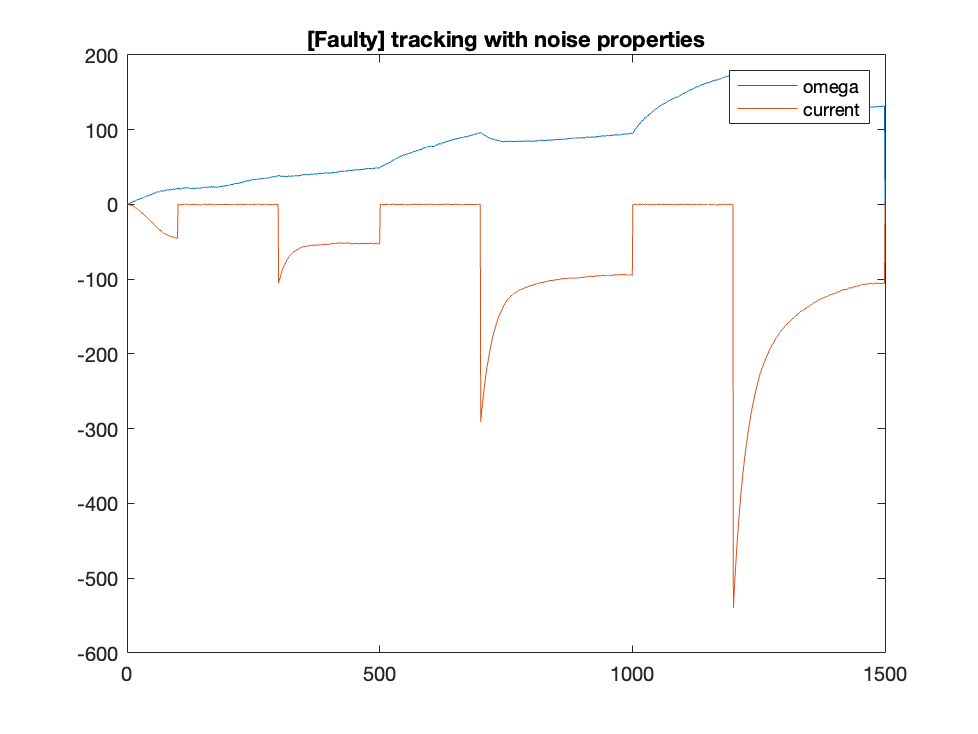


figure(6);
plot(y(1,:));
hold on
plot(y(2,:));
legend("omega","current")
title("[Faulty] tracking with noise properties")
hold off

## Problem 3:

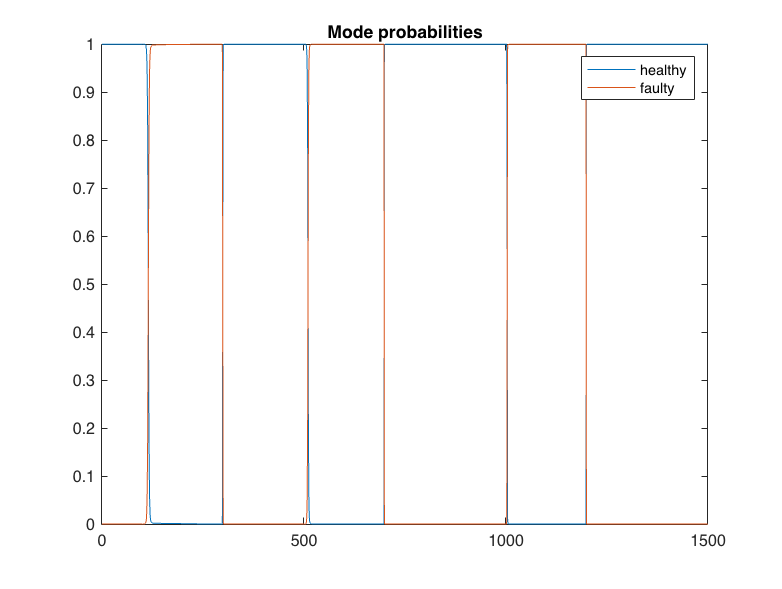

% Design IMM algorithm
% Evaluate unmeasurable load
% Detect faults of current sensor
% p12 = 0.001 transition to fault
% p21 = 0.005 recovery


x0 = [0; 0];
prob_init = [1; 0];
xhat0 = cell(2, 1);

xhat = cell(1, 2);
xhat{1} = zeros(2, N);
xhat{2} = zeros(2, N);
xhat{1}(:, 1) = x0;
xhat{2}(:, 1) = x0;

xhatc = zeros(2, N);
xTLoad = zeros(1, N);
xTLoad(1) = 0;
H = cell(2, 1);
H{1} = Ch;
H{2} = Cf;

P = cell(2, N);
P{1,1} = Qh;
P{2,1} = Qf;

Qc = cell(2, 1);
Qc{1} = Qh;
Qc{2} = Qf;

Rc = cell(2, 1);
Rc{1} = 1000*eye(2);
Rc{2} = 1000*eye(2);

prob_vec = zeros(2, N);
result_vec = zeros(1, N);
prob_vec(:, 1) = prob_init;
Lk = cell(2, N);
Sk = cell(2, N);

r = cell(2, N);
W = cell(2, N);

% Interaction
Pt = [0.999, 0.001; 
      0.005, 0.995];

mu = [1;0];
c_bar = zeros(2, 1);
mu_mix = zeros(2, 2);

for i = 2:N
    c_bar(1) = Pt(1, 1)*mu(1) + Pt(2, 1)*mu(2);
    c_bar(2) = Pt(1, 2)*mu(1) + Pt(2, 2)*mu(2);
    
    mu_mix = [(1/c_bar(1))*Pt(1,1)*mu(1), (1/c_bar(2))*Pt(1,2)*mu(1);
              (1/c_bar(1))*Pt(2,1)*mu(2), (1/c_bar(2))*Pt(2,2)*mu(2)];
    % filter 1 init state
    xhat0{1} = xhat{1}(:, i-1)*mu_mix(1,1) + xhat{2}(:, i-1)*mu_mix(2,1);
    % filter 2 init state
    xhat0{2} = xhat{1}(:, i-1)*mu_mix(1,2) + xhat{2}(:, i-1)*mu_mix(2,2);
    
    
    % filter 1 init cov
    P0{1} = (P{1, i-1} + (xhat{1}(:, i-1) - xhat0{1})*(xhat{1}(:, i-1) - xhat0{1})')*mu_mix(1,1) + ...
            (P{2, i-1} + (xhat{2}(:, i-1) - xhat0{1})*(xhat{2}(:, i-1) - xhat0{1})')*mu_mix(2,1);
    
    % filter 2 init cov
    P0{2} = (P{1, i-1} + (xhat{1}(:, i-1) - xhat0{2})*(xhat{1}(:, i-1) - xhat0{2})')*mu_mix(1,2) + ...
            (P{2, i-1} + (xhat{2}(:, i-1) - xhat0{2})*(xhat{2}(:, i-1) - xhat0{2})')*mu_mix(2,2);

    % Filtering
    % Prediction step
    % filter 1
    xhat{1}(:, i) = Ah*xhat0{1} + Bh*u(:,i-1);
    % filter 2
    xhat{2}(:, i) = Af*xhat0{2} + Bf*u(:,i-1);
    
    %% filter 1
    P{1, i} = Ah*P0{1}*Ah' + Qc{1};
    %% filter 2
    P{2, i} = Af*P0{2}*Af' + Qc{2};
    
    % Correction step
    % innovation
    r{1, i} = y(:,i) - H{1}*xhat{1}(:, i);
    r{2, i} = y(:,i) - H{2}*xhat{2}(:, i);

    % residual covariance
    Sk{1, i} = H{1}*P{1, i}*H{1}' + Rc{1};
    Sk{2, i} = H{2}*P{2, i}*H{2}' + Rc{2};
    
    % Kalman gain
    W{1, i} = P{1, i}*H{1}'*inv((Sk{1, i}));
    W{2, i} = P{2, i}*H{2}'*inv((Sk{2, i}));

    % update
    xhat{1}(:, i) = xhat{1}(:, i) + W{1, i}*r{1, i};
    xhat{2}(:, i) = xhat{2}(:, i) + W{2, i}*r{2, i};
    
    P{1, i} = P{1, i} - W{1, i}*H{1}*P{1, i};
    P{2, i} = P{2, i} - W{2, i}*H{2}*P{2, i};

    % Likelihood
    Lk{1, i} = mvnpdf(r{1, i}, 0, Sk{1, i});
    Lk{2, i} = mvnpdf(r{2, i}, 0, Sk{2, i});
    
    mu(1) = Lk{1, i}*(Pt(1,1)*mu(1)+Pt(2,1)*mu(2));
    mu(2) = Lk{2, i}*(Pt(1,2)*mu(1)+Pt(2,2)*mu(2));
    
    c = sum(mu, 'all');
    mu = mu*(1/c);
    prob1 = mu(1);
    prob2 = mu(2);

    % Combination of two filters
    prob_vec(:, i) = mu;
    result_vec(i) = prob_vec(2,i);
    xhatc(:, i) = xhat{1}(:, i)*prob1 + xhat{2}(:, i)*prob2;
    Pc{i} = (P{1, i} + (xhat{1}(:, i) - xhatc(:, i))*(xhat{1}(:, i) - xhatc(:, i))')*prob1 + ...
            (P{2, i} + (xhat{2}(:, i) - xhatc(:, i))*(xhat{2}(:, i) - xhatc(:, i))')*prob2;  
    xTLoad_h = (1/(Bh(1,2))*(xhat{1}(1,i)-Ah(1,1)*xhat{1}(1,i-1) - Ah(1,2)*xhat{1}(2,i-1) - Bh(1,1)*w_ref(i-1)));
    xTLoad_f = (1/(Bf(1,2))*(xhat{2}(1,i)-Af(1,1)*xhat{2}(1,i-1) - Af(1,2)*xhat{2}(2,i-1) - Bf(1,1)*w_ref(i-1)));
    xTLoad(i-1) = xTLoad_h*prob1 + xTLoad_f*prob2;
end


figure(7);
plot(prob_vec(1,:));
hold on
plot(prob_vec(2,:));
title("Mode probabilities");
legend("healthy","faulty");
hold off

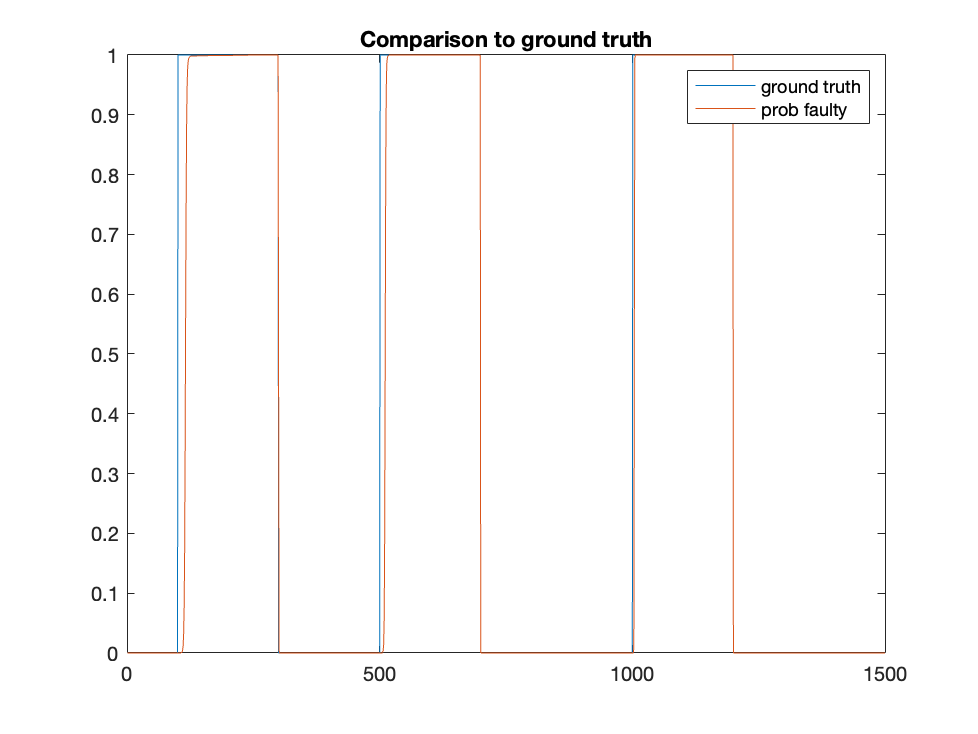


% Analysis of fault detection
figure(8);
plot(fault(:));
hold on
plot(result_vec);
title("Comparison to ground truth");
legend("ground truth","prob faulty");
hold off

disp("Mean Square Error:")

Mean Square Error:


disp(calculateMSE(fault,[0 result_vec]))

    0.1490



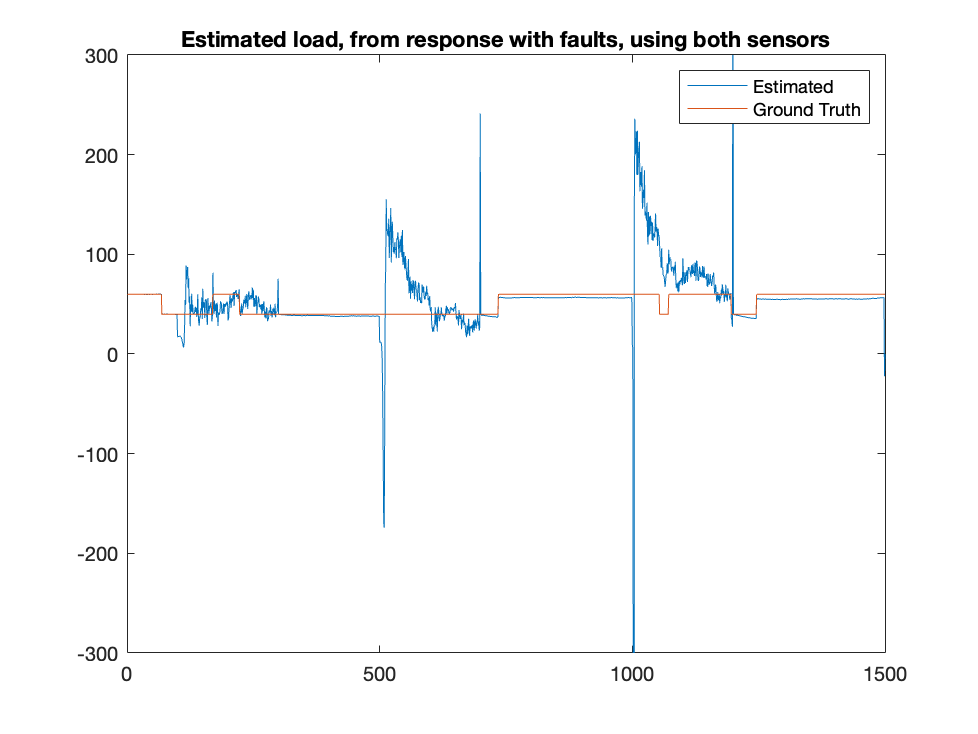



figure(9);
plot(xTLoad);
hold on
plot(Td)
title("Estimated load, from response with faults, using both sensors");
legend("Estimated","Ground Truth");
ylim([-300 300])

disp("Mean Square Error:")

Mean Square Error:


disp(calculateMSE(Td,xTLoad))

   78.1588



## Problem 4:

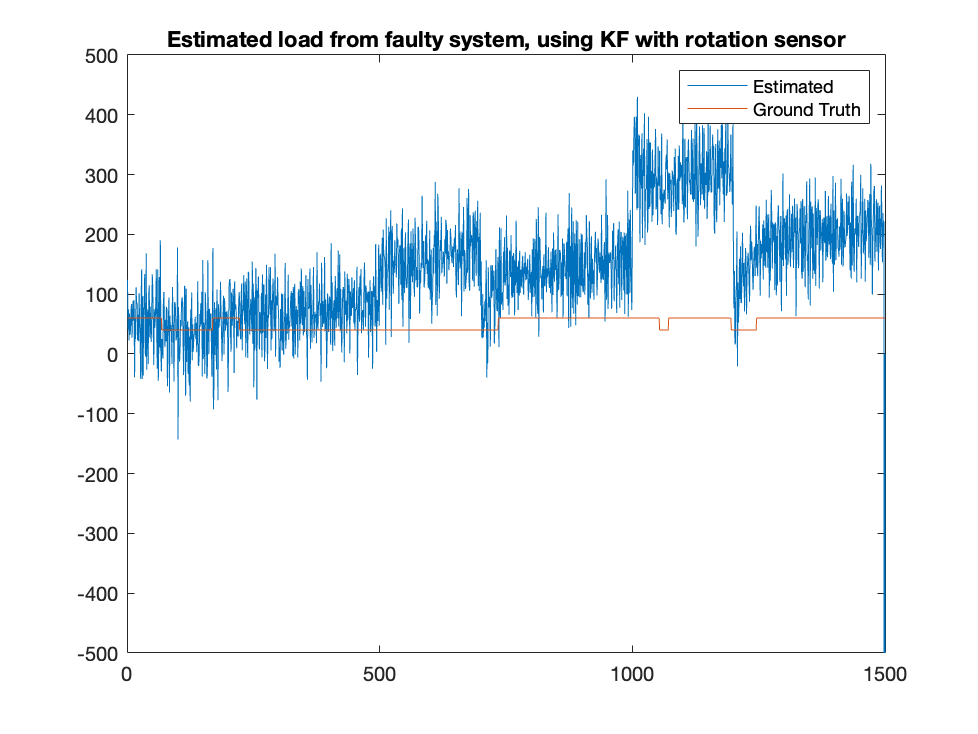

% Analyse the performance of fault detection
% Compare IMM to KF using only rotation speed sensor
% Is it possible to justify use of current sensor?
x0 = [0; 0];

xhat = zeros(2, N);
xhat(:, 1) = x0;
xTLoad = zeros(1, N);
xTLoad(1) = 0;
H = Cf;
P = Qf;
Qc = Qf;
Rc = Rf;
Sk = Sf;

y(2,:) = 0;

for i = 2:N
    % filter 1 init state
    xhat0 = xhat(:,i-1);
    P0 = P;
    % Filtering
    % Prediction step
    xhat(:, i) = Af*xhat0 + Bf*u(:,i-1);
    P = Af*P0*Af' + Qc;
    
    % Correction step
    % innovation
    r = y(:,i) - H*xhat(:, i);
    % residual covariance
    Sk = H*P*H' + Rc;
    % Kalman gain
    W = P*H'/(Sk);
    % update
    xhat(:, i) = xhat(:, i) + W*r; 
    P = P - W*H*P;

    xTLoad(i-1) = (1/(Bh(1,2))*(xhat(1,i)-Ah(1,1)*xhat(1,i-1) - Ah(1,2)*xhat(2,i-1) - Bh(1,1)*w_ref(i-1)));
end

figure(10);
plot(xTLoad);
hold on
plot(Td)
title("Estimated load from faulty system, using KF with rotation sensor");
legend("Estimated","Ground Truth");
hold off
ylim([-500 500])

disp("Mean Square Error:")

Mean Square Error:


disp(calculateMSE(Td,xTLoad))

  435.6976



## Problem 5:

% Lessons learned
% IMM is best suited for fault detection
% KF using only rotation speed sensor is NOT enough for estimation of load
% KF is worse for estimation of load than IMM
% Current sensor must be used

## Additional tools

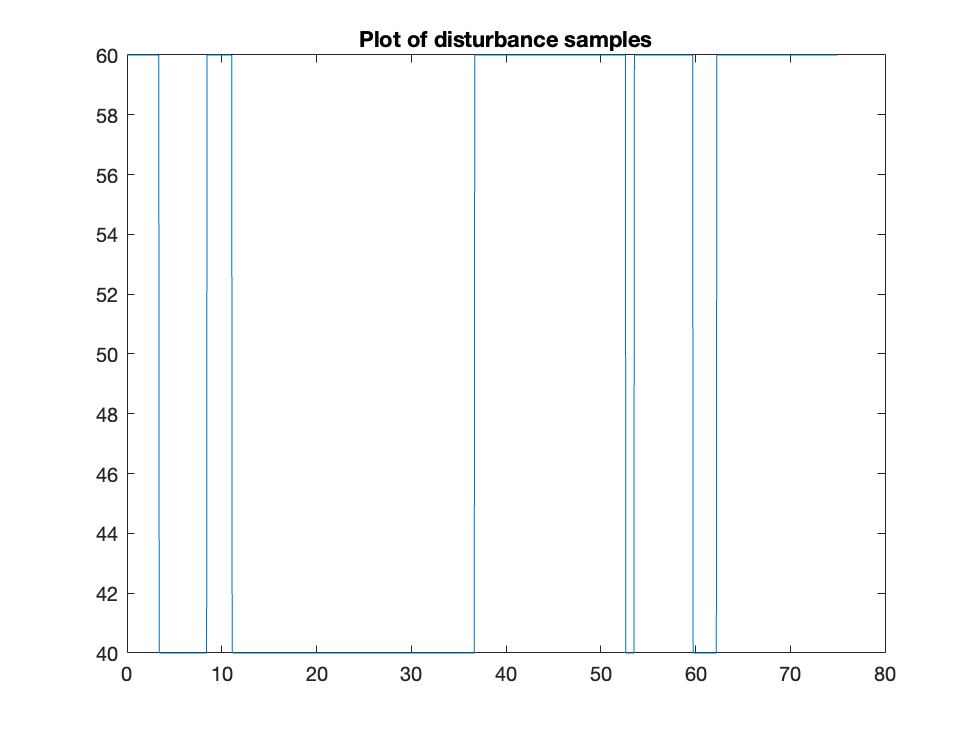

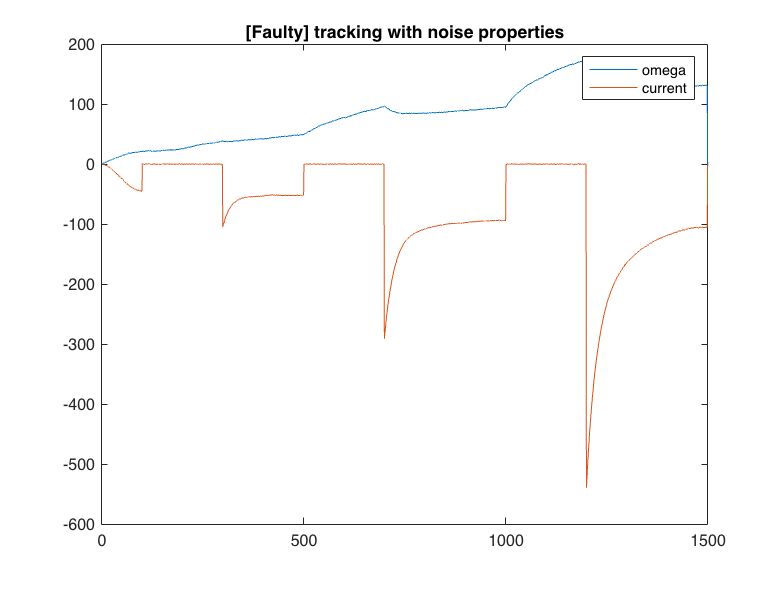

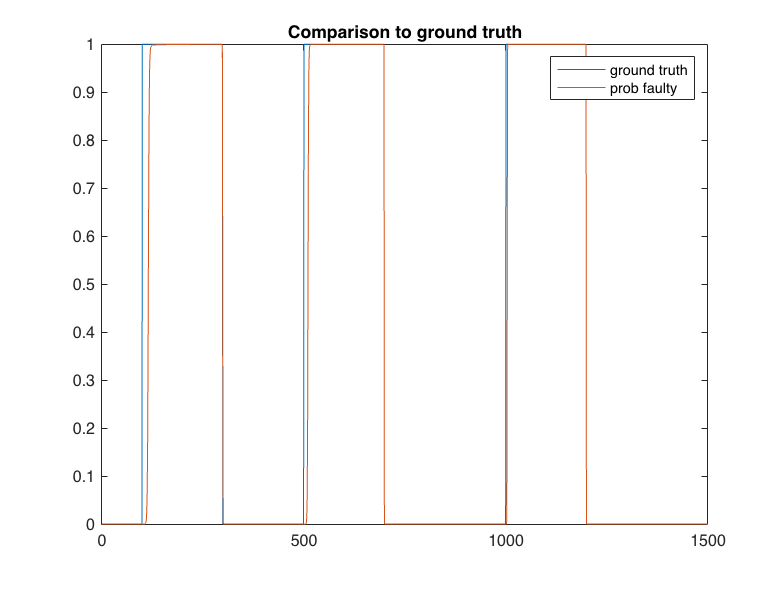

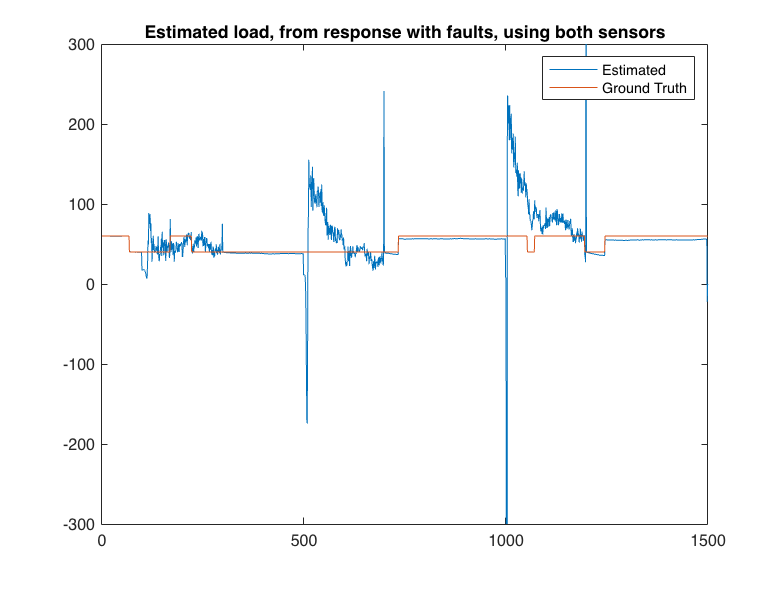

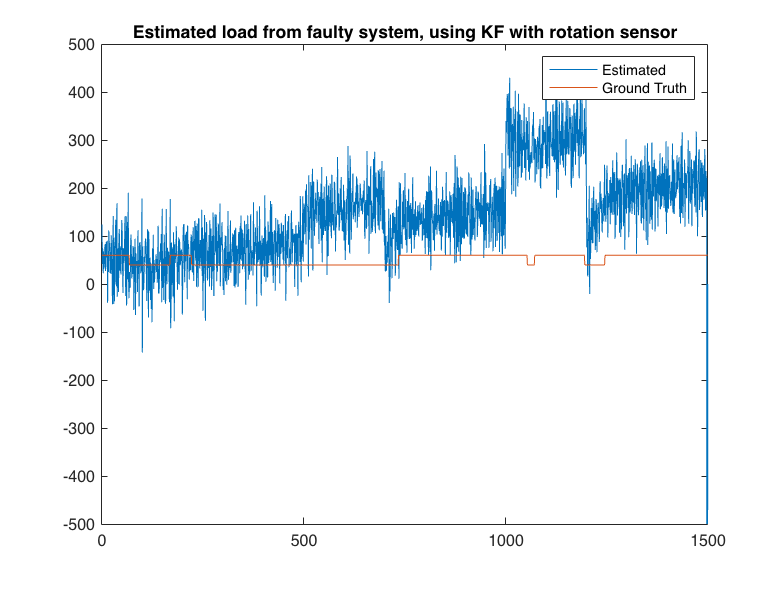

% Storing figures
if storeFigures
    for i=1:10
        filename = strcat('figure_',num2str(i));
        foldername = './figures/';
        saveas(figure(i),fullfile(foldername,filename),'jpg');
    end
end